## Testing bootstrap method for computing IRF estimator S.E.s

clear all
close all
%clc
warning off;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% INPUT SPECIFICATION CHOICES 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

timesample=1; % 1 means 1889-2015; 2 means post WWII
statechoice=1;  % 1 means default unemp threshold; 2 means default ZLB threshold
shockchoice=1; % 1 means news shock; 2 means BP shock
transformation=1; % 1 means Gordon-Krenn; 2 means Hall-Barro-Redlick
taxchoice=0; %0 means no taxes as control; 1 means ad taxy as a control

trend=0; %4 means quartic; 2 means quadratic; 0 means no trend  
nlag=4;% number of lags of control variables
opt=0; % 0 means Newey-West with bandwidth=i; 1 means optimal bandwidth (takes much longer to run)'

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if transformation==1
    disp('Gordon-Krenn')
elseif transformation==2
    disp('Hall-Barro-Redlick')
end

Gordon-Krenn


if shockchoice==1
    disp('News shock')
elseif shockchoice==2
    disp('BP shock')
end

News shock



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hor=20; % horizon for IRFs
clevel= 1.96; % confidence level % 1.96  1.64;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
run('figure_irfs_multipliers_setup.m')

ans = 0.3584

Estimating Linear Model

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%LINEAR
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if trend==4
    x=[constant, t', tsq', tcu', tqu', shock,  xorig]; %complete RHS
    rpos=6; % position of shock
elseif trend==2
    x=[constant, t', tsq', shock,  xorig];
    rpos=4;
elseif trend==0
    x=[constant, shock,  xorig];
    rpos=2;
end

% Generate the standard LP IRFs
[liny, confidencey]=linlp_rc(data,x,hor,rpos,transformation, clevel, opt, 0, nlag);

    0.0221    0.0376    0.0542    0.0607    0.0696    0.0820    0.0863    0.0837    0.0907    0.1036    0.1180    0.1262    0.1263    0.1259    0.1297    0.1162    0.0916    0.0650    0.0513    0.0475

    0.0139    0.0331    0.0337    0.0290    0.0403    0.0489    0.0509    0.0541    0.0676    0.0718    0.0777    0.0837    0.0885    0.0973    0.1084    0.1007    0.0744    0.0577    0.0493    0.0446



Plotting RZ Standard Figures

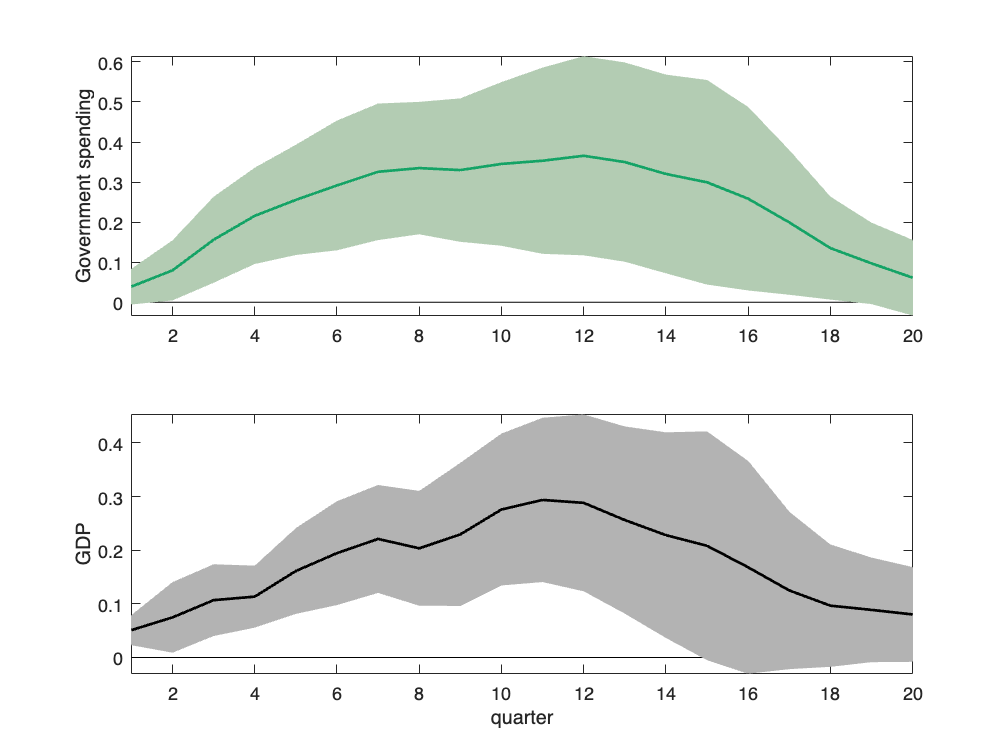

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Figures 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
zz=zeros(1,hor);
i=1;
figure(1)
subplot(2,1,1)
plot(1:1:hor, zz, 'k-')
hold on
% plot CIs
grpyat=[(1:1:hor)', confidencey(1,:,i)'; (hor:-1:1)' confidencey(2,hor:-1:1,i)'];
patch(grpyat(:,1), grpyat(:,2), [0.7 0.8 0.7],'edgecolor', [0.7 0.8 0.7]);
% plot point estimates
plot(1:1:hor, liny(i,:), 'Color', [0.08 0.64 0.4],'LineWidth', 1.5)
axis tight
ylabel('Government spending')

i=2;
subplot(2,1,2)
plot(1:1:hor, zz, 'k-')
hold on
grpyat=[(1:1:hor)', confidencey(1,:,i)'; (hor:-1:1)' confidencey(2,hor:-1:1,i)'];
patch(grpyat(:,1), grpyat(:,2), [0.7 0.7 0.7],'edgecolor', [0.7 0.7 0.7]);
plot(1:1:hor, liny(i,:), 'Color', 'black','LineWidth', 1.5)

axis tight
ylabel('GDP')
xlabel('quarter')

Compute boostrap SEs for comparison

% defining required variables
clear bs_confidencey
close all

[liny, bs_confidencey]=linlp_rc(data,x,hor,rpos,transformation, clevel, opt, 1, nlag);

    0.0094    0.0178    0.0223    0.0251    0.0362    0.0387    0.0392    0.0451    0.0534    0.0394    0.0510    0.0525    0.0604    0.0537    0.0582    0.0542    0.0608    0.0589    0.0532    0.0627

    0.0144    0.0225    0.0363    0.0387    0.0420    0.0473    0.0461    0.0545    0.0561    0.0553    0.0625    0.0559    0.0659    0.0679    0.0640    0.0670    0.0676    0.0713    0.0741    0.0695



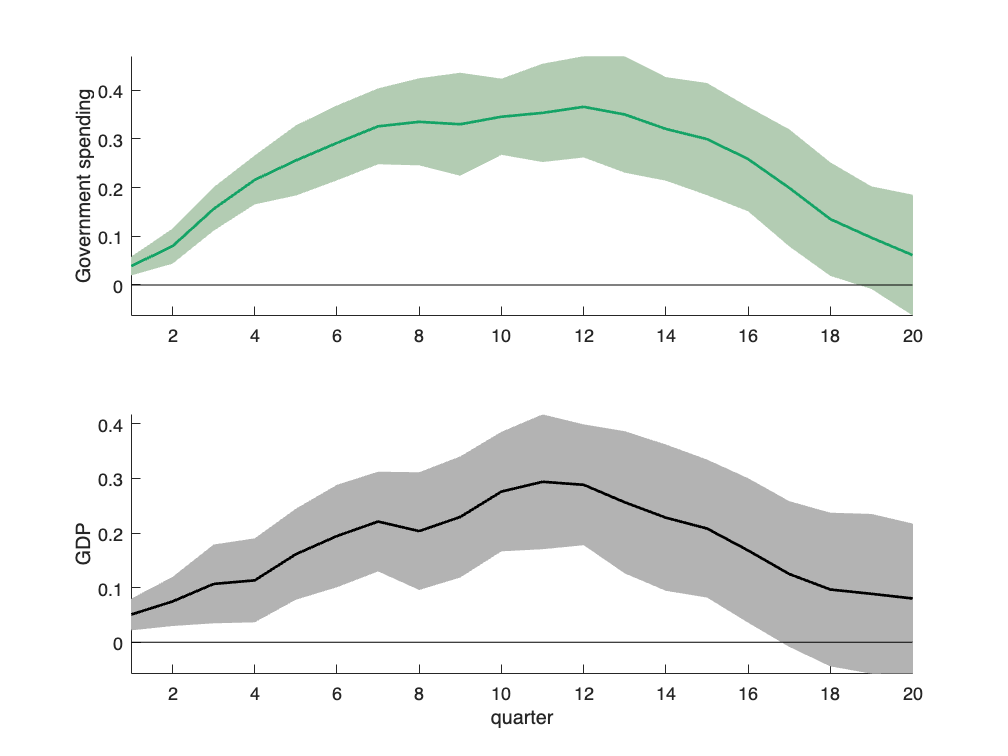

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Figures 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
zz=zeros(1,hor);
i=1;
figure(2)
subplot(2,1,1)
hold on
% plot CIs
grpyat=[(1:1:hor)', bs_confidencey(1,:,i)'; (hor:-1:1)' bs_confidencey(2,hor:-1:1,i)'];
patch(grpyat(:,1), grpyat(:,2), [0.7 0.8 0.7],'edgecolor', [0.7 0.8 0.7]);
% plot point estimates
plot(1:1:hor, liny(i,:), 'Color', [0.08 0.64 0.4],'LineWidth', 1.5)
plot(1:1:hor, zz, 'k-')
axis tight
ylabel('Government spending')

i=2;
subplot(2,1,2)
hold on
grpyat=[(1:1:hor)', bs_confidencey(1,:,i)'; (hor:-1:1)' bs_confidencey(2,hor:-1:1,i)'];
patch(grpyat(:,1), grpyat(:,2), [0.7 0.7 0.7],'edgecolor', [0.7 0.7 0.7]);
plot(1:1:hor, liny(i,:), 'Color', 'black','LineWidth', 1.5)
plot(1:1:hor, zz, 'k-')
axis tight
ylabel('GDP')
xlabel('quarter')